load("C:\Users\Asus\Studia\Projekt IPS\dane - semestr 5\MATLAB_project\ab_diff_zestaw.mat")

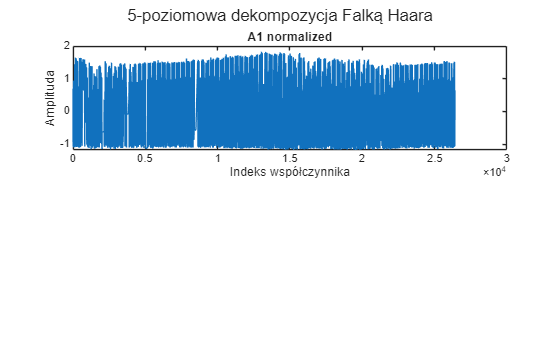

function results = model_A1(A1, forecast_horizont)
    A11 = A1(:,1);

    SARIMA_A113 = arima('Constant',NaN,'ARLags',1:2,'D',0,'MALags',1,'SARLags',50,'Seasonality',50,'SMALags',50,'Distribution','Gaussian');
    SARIMA_A113 = estimate(SARIMA_A113,A11,'Display','off');

    results = forecast(SARIMA_A113, forecast_horizont, 'Y0', A1);
end


% Wzór R2_1 (Standardowy Współczynnik Determinacji)
R2_classic = @(y_true, y_pred) 1 - (sum((y_true(:) - y_pred(:)).^2) / sum((y_true(:) - mean(y_true(:))).^2));

% Wzór R2_2 (Frakcja Wyjaśnionej Wariancji)
R2_alt = @(y_true, y_pred) sum((y_pred(:) - mean(y_true(:))).^2) / sum((y_true(:) - mean(y_true(:))).^2);


% ZBIÓR TRENINGOWY
[c, l] = wavedec(ab_diff_train_norm, 5, 'Haar');

% Pobierz współczynniki aproksymacji A i szczegółów D
A1 = appcoef(c, l, 'haar', 1);
A5 = appcoef(c, l, 'haar', 5);

D5 = detcoef(c, l, 5);
D4 = detcoef(c, l, 4);
D3 = detcoef(c, l, 3);
D2 = detcoef(c, l, 2);
D1 = detcoef(c, l, 1);

% normalizacja współczynników
[A1_norm, center_A1, scale_A1] = normalize(A1);

% 2. RYSOWANIE WYKRESÓW
figure;

subplot(2, 1, 1);
plot(A1_norm);
title('A1 normalized');
xlabel('Indeks współczynnika');
ylabel('Amplituda');

sgtitle('5-poziomowa dekompozycja Falką Haara');


% TEST
[c_test, l_test] = wavedec(ab_diff_test_norm, 5, 'Haar');

% Pobierz współczynniki aproksymacji (Trend) z poziomu 5
A1_test = appcoef(c_test, l_test, 'haar', 1);
A5_test = appcoef(c_test, l_test, 'haar', 5);

D5_test = detcoef(c_test, l_test, 5);
D4_test = detcoef(c_test, l_test, 4);
D3_test = detcoef(c_test, l_test, 3);
D2_test = detcoef(c_test, l_test, 2);
D1_test = detcoef(c_test, l_test, 1);

% Normalizacja współczynników testowych
A1_test_norm = (A1_test - center_A1) ./ scale_A1;

dlugosc_testu_oryginalna = 2880; % Horyzont w oryginalnej dziedzinie czasu (2880 próbek)

dlugosc_testu_A1 = ceil(dlugosc_testu_oryginalna / 2);

% Przewidywania A1 - model hybrydowy
A1_pred_norm = model_A1(A1_norm, dlugosc_testu_A1)';

A1_pred_norm =     0.5217    0.3127    0.3001    0.1499    0.0650    0.2174    0.2303    0.1754    0.1479    0.0035   -0.0224   -0.1249   -0.0835   -0.1872   -0.1794   -0.0202    0.1753    0.1797    0.2740    0.2695    0.2795    0.1909    0.2262    0.1340    0.1795    0.1918    0.2101    0.2196    0.2722    0.3200   -0.1005   -0.3128   -0.2426   -0.3051   -0.3422   -0.2566   -0.1749   -0.0062   -0.0279    0.0930    0.1654   -0.1862   -0.1678   -0.1980   -0.2134   -0.1915   -0.1039   -0.1721   -0.0375    0.1781


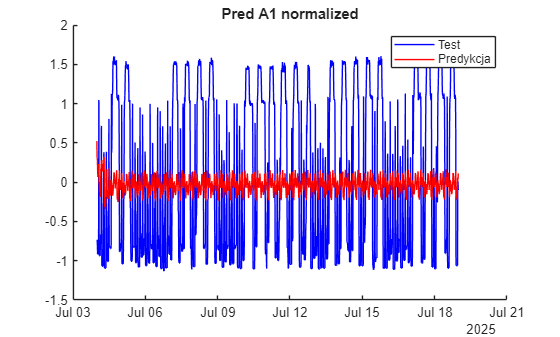

% Narysuj wykres
figure;
hold on;
plot(ab_diff_test.Time(1:dlugosc_testu_A1), A1_test_norm(1:dlugosc_testu_A1), 'Color','blue', 'DisplayName','Test');
plot(ab_diff_test.Time(1:dlugosc_testu_A1), A1_pred_norm, 'Color','red','DisplayName','Predykcja');
title('Pred A1 normalized');
legend;

% DENORMALIZACJA
% Odwracamy proces: x = y * scale + center
A1_pred = (A1_pred_norm .* scale_A1) + center_A1;

D1_pred = zeros(length(A1_pred),1)';

final_prediction = idwt(A1_pred, D1_pred,'haar');      % podejście: A1 sarima

y_test = ab_diff_test_norm(1:length(final_prediction))';

mae_score = mae(y_test, final_prediction)

mae_score = 0.3249

mape_score = mape(y_test, final_prediction)

mape_score = 85.5030

rmse_score = rmse(y_test, final_prediction)

rmse_score = 0.3480

r2_classic = R2_classic(y_test, final_prediction)

r2_classic = -0.0107

r2_alt = R2_alt(y_test, final_prediction)

r2_alt = 0.0147

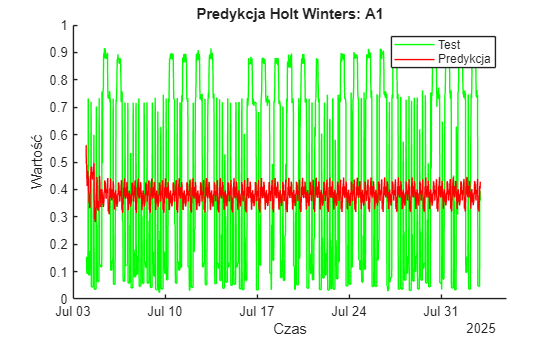


figure;
hold on;
%plot(ab_diff_train.Time, ab_diff_train_norm, 'Color','blue','DisplayName','Trening');
plot(ab_diff_test.Time(1:length(final_prediction)), ab_diff_test_norm(1:length(final_prediction)), 'Color','green','DisplayName','Test');
plot(ab_diff_test.Time(1:length(final_prediction)), final_prediction, 'Color','red','DisplayName','Predykcja');
xlabel('Czas');
ylabel('Wartość');
title("Predykcja Holt Winters: A1")
legend;

% Tworzenie tabeli z czasem, danymi i predykcją
T_z_czasem = table(ab_diff_test.Time(1:dlugosc_testu_oryginalna), ...
                   ab_diff_test_norm(1:dlugosc_testu_oryginalna), ...
                   sum_of_4_signals_test(1:dlugosc_testu_oryginalna), ...
    'VariableNames', {'Czas', 'Dane_Prawdziwe', 'Predykcja'});

writetable(T_z_czasem, 'pred_ab_A1_SARIMA_month.xlsx');